# Homomorphic Filtering of an Image

Eben Emmanuel

2048009

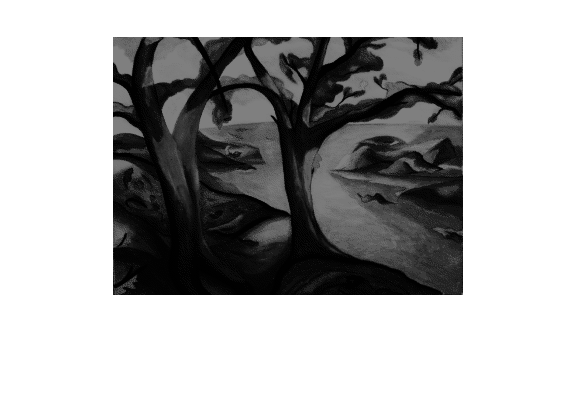

a = imread('trees.tif');
imshow(a);     % Original Image 

## The first step is to convert the input image to the log domain. Before that we will also convert the image to floating-point type.

I = im2double(a);
I = log(1 + I);     % Log Transform

## The next step is to do high-pass filtering. 

- We will construct a frequency-domain high-pass filter. There are different types of high-pass filters you can construct, such as Gaussian, Butterworth, and Chebychev filters. 

- We will construct a simple **Gaussian high-pass filter** directly in the frequency domain.

M = 2*size(I,1) + 1;
N = 2*size(I,2) + 1;

## Next, we choose a standard deviation for the Gaussian which determines the bandwidth of low-frequency band that will be filtered out.

sigma = 10;

% And create the high-pass filter.
[X, Y] = meshgrid(1:N,1:M);
centerX = ceil(N/2);
centerY = ceil(M/2);
gaussianNumerator = (X - centerX).^2 + (Y - centerY).^2;
H = exp(-gaussianNumerator./(2*sigma.^2));          %%% Low-pass Filter
H = 1 - H;          %%% High-pass Filter

## Couple of things to note here. 

- We formulate a low-pass filter and then subtracted it from 1 to get the high-pass filter.

- This is a centered filter in that the zero-frequency is at the center.

% We can rearrange the filter in the uncentered format using fftshift.
H = fftshift(H);

## Next, we high-pass filter the log-transformed image in the frequency domain. 

- We compute the FFT of the log-transformed image with zero-padding using the fft2 syntax that allows us to simply pass in size of the padded image.

- Then we apply the high-pass filter and compute the inverse-FFT. 

- Finally, we crop the image back to the original unpadded size.

If = fft2(I, M, N);
Iout = real(ifft2(H.*If));
Iout = Iout(1:size(I,1),1:size(I,2));


## The last step is to apply the exponential function to invert the log-transform and get the homomorphic filtered image.

Ihmf = exp(Iout) - 1;

## Let's look at the original and the homomorphic-filtered images together.

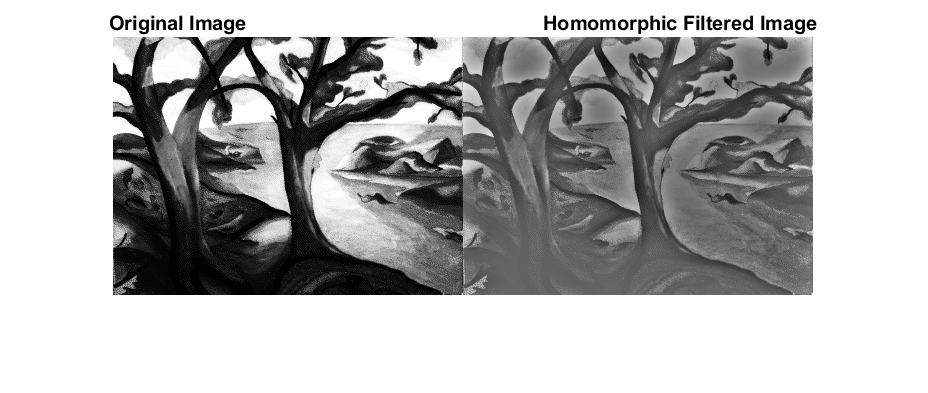

imshowpair(I, Ihmf, 'montage')
title('Original Image                                                      Homomorphic Filtered Image');

- The original image is on the left and the filtered image is on the right. 

- If you compare the two images you can see that the gradual change in illumination in the left image has been corrected to a large extent in the image on the right.

## REFERENCE

- [https://www.coursera.org/lecture/digital/homomorhpic-filtering-CQZsZ](https://www.coursera.org/lecture/digital/homomorhpic-filtering-CQZsZ)

- [https://blogs.mathworks.com/steve/2013/06/25/homomorphic-filtering-part-1/](https://blogs.mathworks.com/steve/2013/06/25/homomorphic-filtering-part-1/)

- [https://www.ques10.com/p/29952/explain-homomorphic-filters/](https://www.ques10.com/p/29952/explain-homomorphic-filters/)